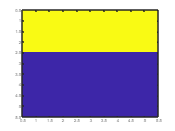

N =   Image with properties:

           CData: [5×5 uint8]
    CDataMapping: 'scaled'

  Show all properties


I = imread("C:\Users\pooja\Downloads\corner.jpg");
imSz = size(I);
patchSz = [5 5];
xIdxs = [1:patchSz(2):imSz(2) imSz(2)+1];
yIdxs = [1:patchSz(1):imSz(1) imSz(1)+1];
patches = cell(length(yIdxs)-1,length(xIdxs)-1);
for i = 1:length(yIdxs)-1
    Isub = I(yIdxs(i):yIdxs(i+1)-1,:);
    for j = 1:length(xIdxs)-1
        patches{i,j} = Isub(:,xIdxs(j):xIdxs(j+1)-1);
    end
end
N= imagesc(patches{27,30})

N

N =   Image with properties:

           CData: [5×5 uint8]
    CDataMapping: 'scaled'

  Show all properties
